## Modélisation de l'activité électrique du cerveau 

#### I. Système à 2 neurones

#### Q1 Exploration

On se propose ici de mettre en place un code avec curseurs pour représenter la variation des courbes s1, s2 selon la variatiation de différents paramètres

clear all;
close all;
clc;

% Définition des fonctions
Phi1 = @(x) max(0,x);
Phi2 = @(x, b) 1 ./ (1 + exp(-b*x));

function [t, s] = euler(W, B, s0, lambda, tspan, phi_choice, b_param)
    N = 1000;
    pas = tspan(2)/N;
    
    % Choisir la fonction selon phi_choice
    if phi_choice == 1
        Phi = @(x) max(0,x);
    else
        Phi = @(x) 1 ./ (1 + exp(-b_param*x));
    end
    
    f = @(t, s) -lambda * s + Phi(W * s + B); % equation
    
    t = zeros(N + 1, 1);
    s = zeros(N + 1, 2);
    
    t(1) = tspan(1);
    s(1, :) = s0;
    
    % Euler
    for i = 1:N
        f_i = f(t(i), s(i, :)');
        s(i+1, :) = s(i, :) + pas * f_i';
        t(i+1) = t(i) + pas;
    end
end

% Initialisation des paramètres
W = [1, 1; 1, 1];
B = [1; 1];
s0 = [1; 1];
lambda_val = 2;
tspan = [0 10];
phi_choice = 1; % 1 pour Phi1, 2 pour Phi2
b_param = 1; % Paramètre b pour Phi2

% Fonction de tracé
function tracer_graph(lambda_val, s_01, s_02, B1, B2, w11, w12, w21, w22, phi_choice, b_param)
    W = [w11, w12; w21, w22];
    B = [B1; B2];
    s0 = [s_01; s_02];
    tspan = [0 10];
    
    [t, s] = euler(W, B, s0, lambda_val, tspan, phi_choice, b_param);
    
    plot(t, s, 'LineWidth', 2);
    xlabel('Temps (t)', 'FontSize', 12);
    ylabel('États s_i(t)', 'FontSize', 12);
    grid on;
    legend('s_1(t)', 's_2(t)', 'Location', 'best', 'FontSize', 11);
    
    % Titre avec indication de la fonction choisie
    if phi_choice == 1
        titre = 'Modélisation avec Phi1: max(0,x)';
    else
        titre = sprintf('Modélisation avec Phi2: sigmoïde (b=%.1f)', b_param);
    end
    title(titre);
end

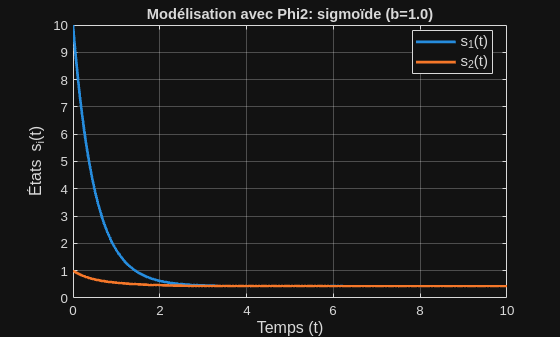

lambda_val =2;
s_01 =10;
s_02 =1;
B1 =1;
B2 =1;
w11 =1;
w12 =1;
w21 =1;
w22 =1;
b_param =1;
phi_choice = 2;
%% Tracé
tracer_graph(lambda_val, s_01, s_02, B1, B2, w11, w12, w21, w22, phi_choice, b_param);

#### Conclusion

Conclusion pertinente

####     II. Système à n neurones

#### Q2/ Exploration

%Code

#### Q3/ Système à n neurones - On veut trouver numériquement W ∗ qui minimise H(W ) sur Mn (R)

- Calcul des dérivées partielles

%code

        2. Utilisation d'une descente de gradient sur la fonction H

%code

####     III. Prise en compte des incertitudes

#### Q4/ Propagation des incertitudes

- Hypothèse: les données initiales du système sont distribuées selon des lois normales indépendantes

%code

        2. Incertitude sur le calcul

%code

        3. Variabilité ur les données d'entrée

%code

#### **Q5/ **

%code